# ACO Assignment 2022 Q5 Linear Quadratic Gaussian Controller

## Load Simplfied State-space plant

clc 
clear 
load reduced_model.mat
 %#ok<*NOPTS>

## Define some variables for use

s = zpk('s') %for defining transfer functions

s =
 
  s
 
Continuous-time zero/pole/gain model.



om_rad = logspace(-2,5,1001); %define logspace range for plotting bode plot
om_rad_lin = linspace(12,17,1001); %define range for plotting highlight of frequency range

bw_gamma_rad = 10*0.2*2*pi %define target azimuth motion bandwith, 2pi radians is one hertz

bw_gamma_rad = 12.5664

bw_alpha_rad = 10*0.25*2*pi %define target elevation motion bandwith, 2pi radians is one hertz

bw_alpha_rad = 15.7080

    
ny = 4; %define the output dimension, for identity matrices    
THE_AXES = [-110 30];


## Design Q and R for Kalman Filter

%Define covariance matrix Q
% Q_KF = diag([0 1e3 0 5e-3]) %Set 1
Q_KF = diag([0 5e5 0 5e-3]); %Set 2
%Define noise power
% R_KF = diag([1e-4 1e-8]) %Set 1
R_KF = diag([5e-4 1e-8]) %Set 2

R_KF = 	1.0e+-3 *

    0.5000         0
         0    0.0000


## Design weights for LQR


%Pernalize for performance, smaller means don't care about performance as
%much
% Q_LQR_gamma = 1e3; %Set 1
Q_LQR_gamma = 1e4; %Set 2
Q_LQR_dgamma = 1;
% Q_LQR_alpha = 1; %Set 1
Q_LQR_alpha = 1e6; %Set 2
Q_LQR_dalpha = 1;

Q_LQR = mdiag (Q_LQR_gamma,Q_LQR_dgamma,Q_LQR_alpha,Q_LQR_dalpha);

%Penalize for effort, smaller means more effort is ok
R_LQR_gamma = 1e3%/(s + bw_gamma_rad); %Set 1

R_LQR_gamma = 1000

% R_LQR_alpha = 1e1;%/(s + bw_alpha_rad); %Set 1
R_LQR_alpha = 5e4;%/(s + bw_alpha_rad); %Set 2

R_LQR = mdiag(R_LQR_gamma,R_LQR_alpha);
N = 2;

## Generating the LQR

[Clqr,S,e] = lqr(Pred,Q_LQR,R_LQR)

Clqr =     3.1623    0.3167   -0.0000   -0.0000
   -0.0000    0.0000    4.4721    0.3781


S = 	1.0e+04 *

    0.1057    0.0055   -0.0000   -0.0000
    0.0055    0.0006   -0.0000   -0.0000
   -0.0000   -0.0000    8.8440    0.3903
   -0.0000   -0.0000    0.3903    0.0330


e =   -9.5741 + 9.4616i
  -9.5741 - 9.4616i
 -11.3307 +11.3071i
 -11.3307 -11.3071i



Clqr = ss(Clqr)

Clqr =
 
  D = 
               u1          u2          u3          u4
   y1       3.162      0.3167  -4.957e-14  -5.735e-15
   y2  -9.958e-17   4.871e-18       4.472      0.3781
 
Static gain.



Error using InputOutputModel/subsasgn (line 57)
The "A" and "C" matrices must have the same number of columns.


% Clqr
% Clqr(2,4) = Clqr(2,4)/(s+bw_alpha_rad)

## Find the close loop responses and sensitivity

Llqr = Pred*Clqr

T = feedback(Llqr,eye(4,2));
% T1 = T; %Set 1
T2 = T; %Set 2
S = eye(2,4)-T;

## Plotting the sigma, S and T Responses

figure(3)
clf

subplot(121)
sigma(Pred, 'm-.', Llqr, 'b-', om_rad); %%/ Pred, 'k--'
% ylim(THE_AXES)
tweakAxes;
legend('Pred', 'Llqr', 'Location', 'northeast')

sp9b = subplot(222)

sp9b =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ylim(THE_AXES)  
bodemag(S, 'k-', T, 'b-',  om_rad); %CS, 'k:',
legend
% tweakAxes;
% ylim(THE_AXES)
 ylim(sp9b, THE_AXES)
 ylim(THE_AXES)
 grid on

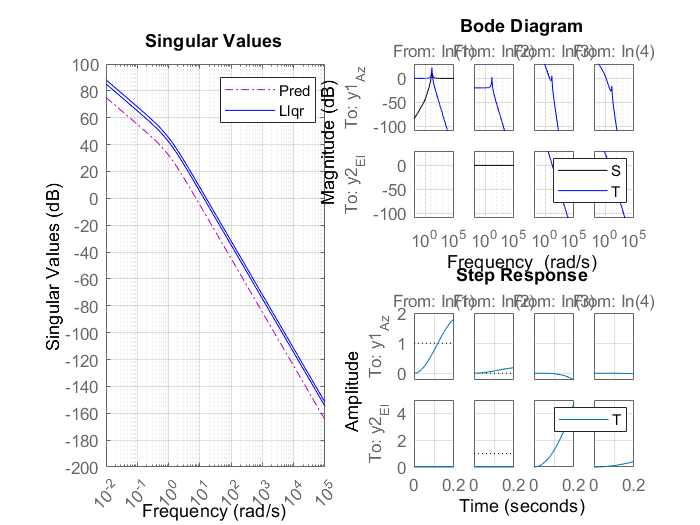

subplot(224)
step(T,0.5);
legend
grid

## Check robustness with multiloop input output diskmargin

[~,MM_Pred] = diskmargin(Pred)

MM_Pred = struct with fields:
           GainMargin: [0.8766 1.1408]
          PhaseMargin: [-7.5267 7.5267]
           DiskMargin: 0.1316
           LowerBound: 0.1316
           UpperBound: 0.1318
            Frequency: 7.5686
    WorstPerturbation: [2×2 ss]


% DGM_P_alpha = DM_P(2).GainMargin;
% DGM_P_gamma = DM_P(1).GainMargin;

% DGMAll_P = [DGM_P_gamma;DGM_P_alpha];
DGM_P = MM_Pred.GainMargin;

% [~,MM_Pw] = diskmargin(Pw)
% % DGM_Pw_alpha = DM_Pw(2).GainMargin
% % DGM_Pw_gamma = DM_Pw(1).GainMargin
% 
% % DGMAll_Pw = [DGM_Pw_gamma;DGM_Pw_alpha];
% DGM_Pw = MM_Pw.GainMargin;

[MM_Llqr] = diskmargin(Llqr) %gets the disk margin of the robustified loop

Error using DynamicSystem/diskmargin (line 95)
The loop transfer matrix L must be square.


DGM_Llqr = MM_Llqr.GainMargin;

## Plot the diskmargins

figure(6)
clf
t6 = tiledlayout(1,3,'TileSpacing','None',"Padding","none");
ax6a = nexttile

ax6a =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0338 0.0432 0.3221 0.9387]
            Units: 'normalized'

  Show all properties


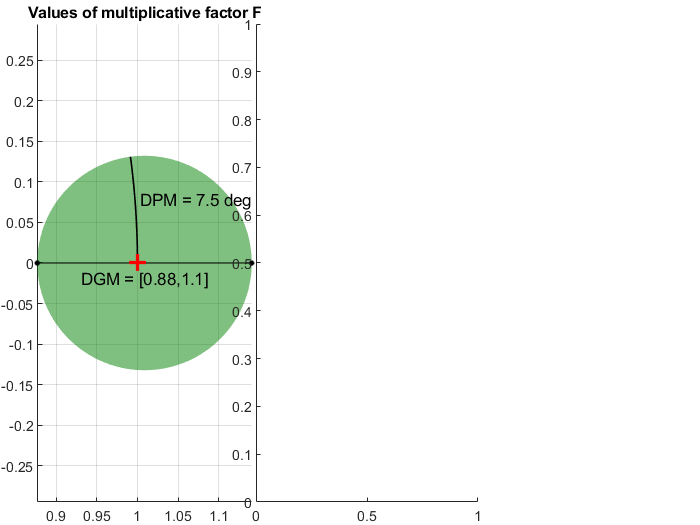

ax6b =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.3652 0.0432 0.3174 0.9113]
            Units: 'normalized'

  Show all properties


diskmarginplot(DGM_P,'disk')

ax6b = nexttile

diskmarginplot(DGM_Pw,'disk')

Unrecognized function or variable 'DGM_Pw'.

linkaxes([ax6a,ax6b],'x')

ax6c = nexttile
diskmarginplot(DGM_Linf,'disk')
ylim([-0.5 0.5])
linkaxes([ax6a,ax6b,ax6c],'x')
linkaxes([ax6a,ax6b,ax6c],'y')
% 
t6title = {'Multiloop I/O Disk Margin','Left: Linear Plant, Middle: Weighted Plant,Right: Robustified Loop'};
% 
% title(t6,{t6title})
title(t6,t6title)

## Observability

Ob = obsv(Pred.A,Pred.C)
unob = length(Pred.A)-rank(Ob)

## Pole-zero Plots

% figure(2)
% clf
% hold on
% pzplot(Pred);
% % pzplot(Clqr);
% pzplot(Llqr);
% legend
% grid on

figure(2)
clf
hold on
ax2a = subplot(1,3,1)
pzplot(Pred);
legend
grid on

ax2b = subplot(1,3,2)
pzplot(T1)
legend
grid on

ax2c = subplot(1,3,3)
pzplot(T2)
legend
grid on
% 
% title({'Pole-zero Plot','Left: Reduced Plant, Middle: LQR Controller,Right: Closed Loop'});
hold off

## Pole and Zero values

z_Pred = zero(Pred)


z_Pred =

  0×1 empty double column vector



p_Pred = pole(Pred)

p_Pred =      0
    -1
     0
    -1



z_T1 = zero(T1)

Unrecognized function or variable 'T1'.

p_T1 = pole(T1)

z_T2 = zero(T2)
p_T2 = pole(T2)